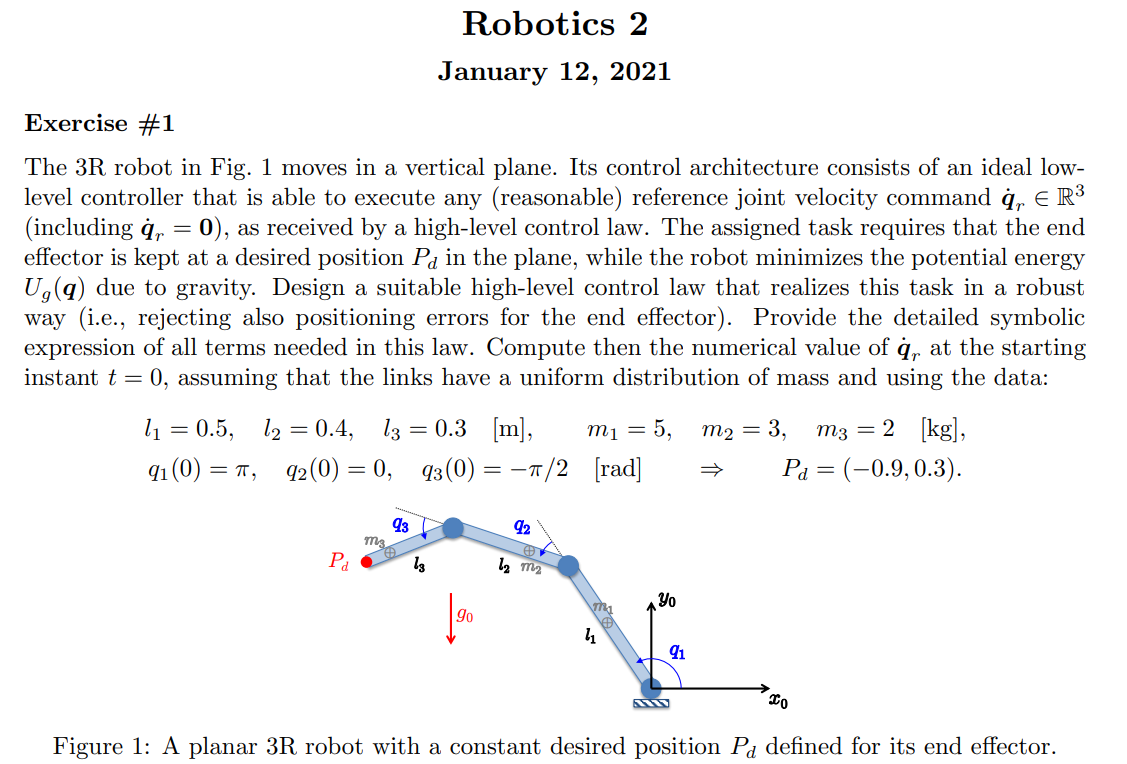

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% 
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% 

% 
% PC_EEShort.J
% PC_EEShort.f

% VarShortRobot.M
% angle_desired=[0,0]
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)

% 
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(PCVar.Pc, z.q, z.l, z.m, z.dc, z.g, z.isMotor)
% 

% U{1}
% PE_short
% g_q

% z.l_=[0.5,0.4,0.3]
% z.dc_=z.l_/2
% z.m_=[5,3,2]
% z.q_=[pi,0,-pi/2]
% to_replace=[z.l',z.dc',z.m',z.q',g0]
% to_replace_=[z.l_,z.dc_,z.m_,z.q_ ,9.8]
% f_=vpa(subs(f,to_replace,to_replace_))
% J_=vpa(subs(J,to_replace,to_replace_))
% J_ps_=vpa(subs(J_ps,to_replace,to_replace_))
% g_q_=vpa(subs(g_q,to_replace,to_replace_))
% 
% q_r_dot_= vpa(g_q_-J_ps_*J_*g_q_)


## Exercise 3

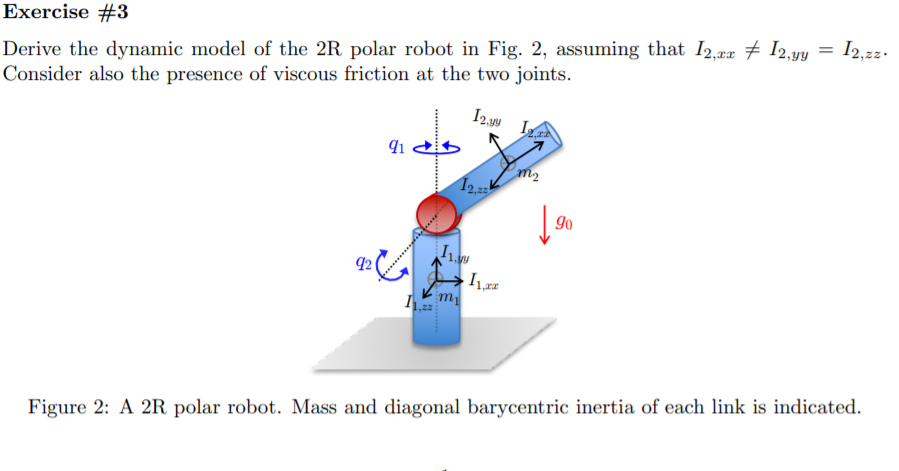

% % close all
% % % Lengths just to test
% % d1_=10;
% % d2_=10;
% % a2_=10;
% % % % De Luca's approach
% %  links = [
% %     Revolute('a', 0, 'alpha', -pi/2 ,'d', 1);
% %     Revolute('a', a2_, 'alpha',0,'d', 0);
% % %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% % %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
% %     ];
% % % 
% %  c600 = SerialLink(links);
% %  c600.teach([0 0],'view','x');
% % % c600.plot([0  pi/2 20 0],'view','x')
% % clear

% 
% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';

% R2Robot=['rr';'zx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% % z.I=I;
% z.methodD=2%2=with DH table, 1 normal mode
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true
% % q = sym('q', [n,1],'real');
% % qd= sym('qd', [n,1],'real');
% % a = sym('a', [n,1],'real');
% % d = sym('d', [n,1],'real');

% z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
%             0       , z.l(2)  , 0   , q(2);]

% 
% %[f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2_xyz(z)

% Pc
% % Trans.PPartial{1}
% vc
% simplify(collect(expand(vc(:,2)'*vc(:,2)),z.q_dot(1)^2))
% Ti(1)
% Ti(2)
% M

% [Msubs, dynamicParameters, aM] = getDynamicParameters(M,z.q,[])

% Msubs
% % 
% 
% % PC_EEShort.J
% % PC_EEShort.f

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

% [C,cac,Csubs,] = getCs(Msubs,z.q,z.q_dot)

% cac

% g_q
% U{:}

% F_v=sym('F',[2,1],'real')
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,g_q,F_v],q,[q_dot.',g0],2)
% [All, dynamicParamsReturn, a]= getDynamicParameters([M,g_q,F_v],q,[q_dot.'],2)

% 
% All

% %complete model
% M_subs_     =All(:,1:n)
% g_q_        =All(:,n+1)
% F_v_        =All(:,n+2)
% M_subs_*z.q_ddot+cac+g_q_+F_v_.*z.q_dot%=Tao

## 6